# interpolate and grid PRIZE mooring data

***Author: Lewis Drysdale, 2021***

### Interpolate, despike, and plot data from moorings deployed and recovered during ArcticPRIZE project

Data were sampled at:

-        2 hour - SBE16

-        6 min - Star-Odi

-        12 mins - SBE 37

clear; close all;

### set directories and gridding parameters

data_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\PRIZE_18_19\DATA\moor_processed'

data_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\PRIZE_18_19\DATA\moor_processed'

plot_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\PRIZE_18_19\figures';

### SET PARAMS FOR GRIDDING AND FILTERING

t_interp    = 1/2; % every 6 hours
z_interp    = 10;   % every 10 metres
y_tol       = [-10 10];    % deviation in PSU allowed by depsike routine
stddy_tol   = 4;           % tolerance range of differences between adjacent values of y
nloop       = 5;           % despike loop number

### Set mooring ID for processing

mooring_id  = 'WEST_18';

### BEGIN DATA PROCESSING

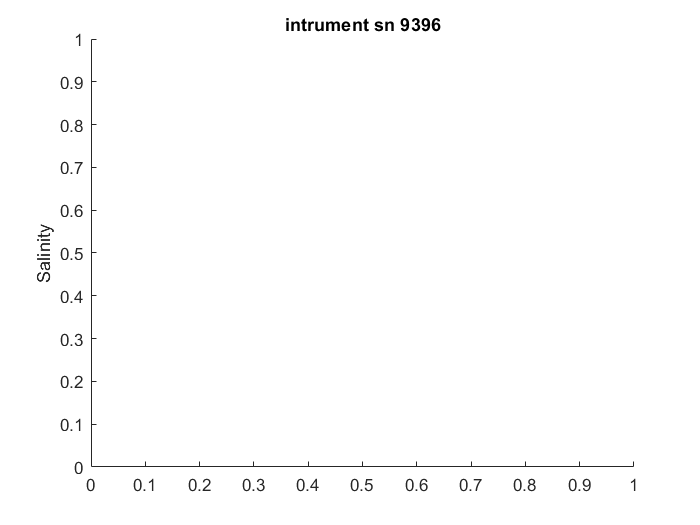

prize_west_18_gridded = struct with fields:
                 temp_filtered: [15×1021 double]
                  sal_filtered: [15×1021 double]
                 pres_filtered: [15×1021 double]
    temp_filtered_interpolated: [20×1021 double]
     sal_filtered_interpolated: [20×1021 double]
                     pres_grid: [20×1 double]
                          temp: [15×1029 double]
                           sal: [15×1029 double]
                          pres: [15×1029 double]
                     time_grid: [1×1029 double]


switch mooring_id

    case 'WEST_17'

        start_date  = datenum('23-Sep-2017');
        end_date    = datenum('14-Jun-2018');

        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_west_17_gridded]=prize_grid_linear_interp(prize_west_17,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,y_tol,stddy_tol,nloop)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_west_17_gridded','prize_west_17');
        
    case 'EAST_17'

        start_date  = datenum('21-Sep-2017');
        end_date    = datenum('17-Jun-2018');

        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_east_17_gridded]=prize_grid_linear_interp(prize_east_17,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,y_tol,stddy_tol,nloop)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_east_17_gridded','prize_east_17');
        
    case 'EAST_18'

        start_date  = datenum('21-June-2018');
        end_date    = datenum('17-Nov-2019');
        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_east_18_gridded]=prize_grid_linear_interp(prize_east_18,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,y_tol,stddy_tol,nloop)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_east_18_gridded','prize_east_18');

    case 'WEST_18'

        start_date  = datenum('21-June-2018');
        end_date    = datenum('17-Nov-2019');

        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_west_18_gridded]=prize_grid_linear_interp(prize_west_18,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,y_tol,stddy_tol,nloop)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_west_18_gridded','prize_west_18');
end

## Plot the data

if strcmpi(mooring_id,'WEST_17')
    data=prize_west_17_gridded;
elseif strcmpi(mooring_id,'EAST_17')
    data=prize_east_17_gridded;
elseif strcmpi(mooring_id,'WEST_18')
    data=prize_west_18_gridded;
elseif strcmpi(mooring_id,'EAST_18')
    data=prize_east_18_gridded;
else
    disp('No data to plot!')
end

### plot the salinity data

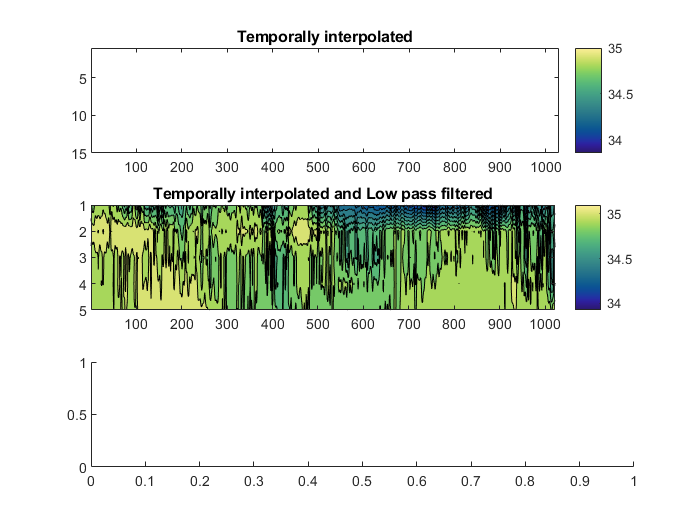

figure(1);
ax(1)=subplot(3,1,1);
[c,h]=contourf(data.sal);
axis ij
cmocean('haline')
colorbar
title('Temporally interpolated')

ax(2)=subplot(3,1,2);
[c,h]=contourf(data.sal_filtered(any(~isnan(data.sal_filtered), 2), :));
axis ij
cmocean('haline')
colorbar
title('Temporally interpolated and Low pass filtered')

ax(3)=subplot(3,1,3);

[c,h]=contourf(data.time_grid,data.pres_grid,data.sal_filtered_interpolated);

Error using contourf (line 57)
The size of X must match the size of Z or the number of columns of Z.

axis ij
datetick('x',12,'keepticks')
cmocean('haline')
colorbar
title('Vertically Interpolated and low pass filtered')

savename=[plot_dir filesep mooring filesep mooring '_salinity_grid'];
print(gcf, '-dpng',savename);

## plot the temperature data

figure(2);
ax(1)=subplot(3,1,1)
[c,h]=contourf(data.temp );
axis ij
cmocean('thermal')
colorbar
title('Temporally interpolated')

ax(2)=subplot(3,1,2)
[c,h]=contourf(data.temp_filtered);
axis ij
cmocean('thermal')
colorbar
title('Temporally interpolated and Low pass filtered')

ax(3)=subplot(3,1,3)
[c,h]=contourf(data.time_grid,data.pres_grid,data.temp_filtered_interpolated);
axis ij
datetick('x',12,'keepticks')
cmocean('thermal')
colorbar
title('Vertically Interpolated and low pass filtered')

savename=[plot_dir filesep mooring filesep mooring '_temp_grid'];
print(gcf, '-dpng',savename);
